[s1,fs1]=audioread('s1.wav');
[s2,fs2]=audioread('s2.wav');
[s3,fs3]=audioread('s3.wav');
[s4,fs4]=audioread('s4.wav');
[s5,fs5]=audioread('s5.wav');
[s6,fs6]=audioread('s6.wav');
out_s1_s6=[s1(4537:22560)' s2(1335:18601)' s3(3693:24000)' s4(3623:20031)' s5(1276:19318)' s6(263:16504)'];
out_male=[s2(1335:18601)' s4(3623:20031)' s5(1276:19318)' s6(263:16504)'];
out_female=[s1(4537:22560)' s3(3693:24000)'];
audiowrite('out_s1_s6.wav',out_s1_s6,fs6);
audiowrite('out_male.wav',out_male,fs6);
audiowrite('out_female.wav',out_female,fs6);

mean_s6=mean(out_s1_s6);
disp(mean_s6);

   1.6186e-04



var_s6=var(out_s1_s6);
disp(var_s6);

    0.0332



max_s6=max(out_s1_s6);
disp(max_s6);

    1.0000



min_s6=min(out_s1_s6);
disp(min_s6);

   -1.0000



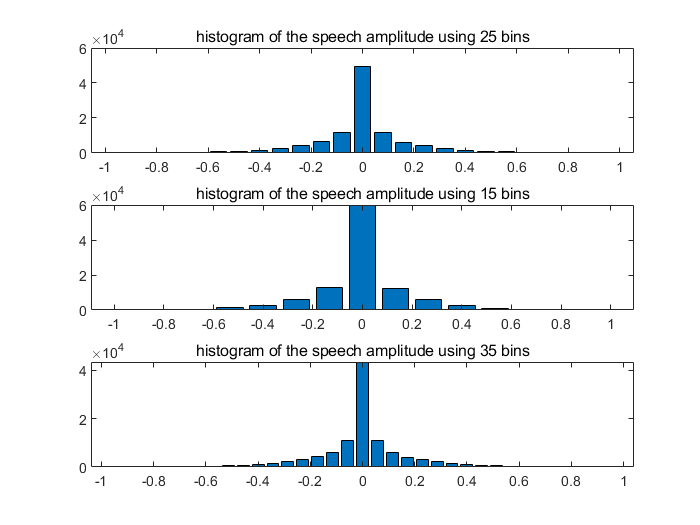

[hist1,center1]=hist(out_s1_s6,25);
[hist2,center2]=hist(out_s1_s6,15);
[hist3,center3]=hist(out_s1_s6,35);
figure;
subplot(3,1,1);bar(center1,hist1);
title('histogram of the speech amplitude using 25 bins');
subplot(3,1,2);bar(center2,hist2);
title('histogram of the speech amplitude using 15 bins');
subplot(3,1,3);bar(center3,hist3);
title('histogram of the speech amplitude using 35 bins');

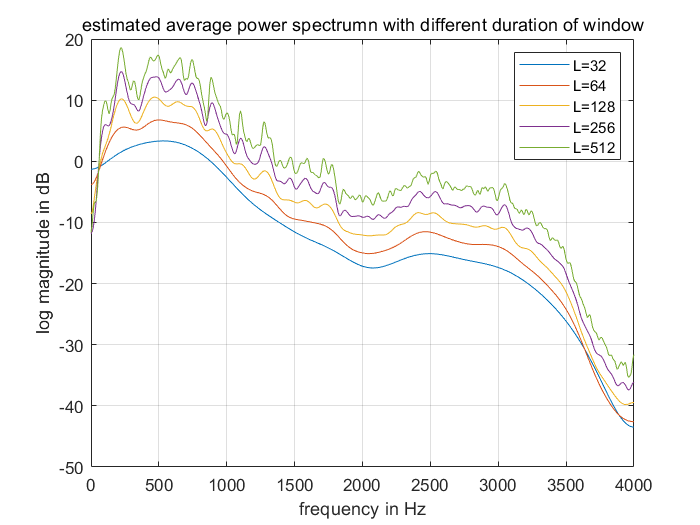


figure;
pspect(out_s1_s6,fs,1024,32);
hold on;
pspect(out_s1_s6,fs,1024,64);
hold on;
pspect(out_s1_s6,fs,1024,128);
hold on;
pspect(out_s1_s6,fs,1024,256);
hold on;
pspect(out_s1_s6,fs,1024,512);
hold on;
title('estimated average power spectrumn with different duration of window');
legend('L=32','L=64','L=128','L=256','L=512');

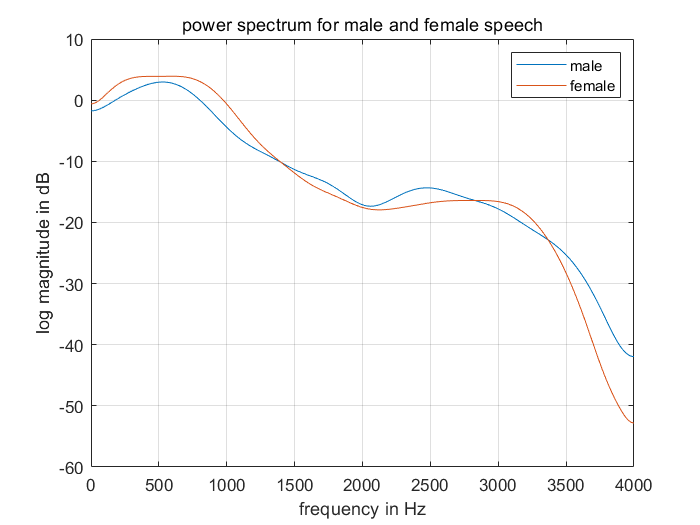


[s_male,fs_male]=audioread('out_male.wav');
[s_female,fs_female]=audioread('out_female.wav');
figure;
pspect(s_male,fs_male,1024,32);
hold on;
pspect(s_female,fs_female,1024,32);
legend('male','female');
title('power spectrum for male and female speech');